close all; clear; clc;

# STv2 Run #1

**file name**: STv2_TM15d_20180928_1.mlx

**keywords:** 

**date of test:** 20180928

**file created by:** 20181001, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %[slugs/ft^3]
% If this wasn't recorded on the day of the test use 0.00228344448402635. 
% Record this in the notes section above

% Motor Specs
diameter = 7.5 /12;
radius = diameter/2;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_TM15d_20180928_1.mat');
time = STv2_TM15d_20180928_1(:,1);                       % [sec]
PWM = STv2_TM15d_20180928_1(:,2);                        % [micro sec]
Q = STv2_TM15d_20180928_1(:,4);                          % [ft.lbf]
T = STv2_TM15d_20180928_1(:,5);                          % [lbf]
Input_V = STv2_TM15d_20180928_1(:,6);                    % [Volts]
Input_A = STv2_TM15d_20180928_1(:,7);                    % [Amps]
rot_speed_rpm = STv2_TM15d_20180928_1(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [rad/sec]
P_in_W = STv2_TM15d_20180928_1(:,9);                     % [Watts]
P_out_W = STv2_TM15d_20180928_1(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = STv2_TM15d_20180928_1(:,11);                 % [%]
Prop_Eff = STv2_TM15d_20180928_1(:,12);                  % [lbf/Watts]
Overall_Eff = STv2_TM15d_20180928_1(:,13);               % [lbf/Watts]  
ESC_Temp = STv2_TM15d_20180928_1(:,14);                  % [F]
Motor_Temp = STv2_TM15d_20180928_1(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]

Settling_time = STv2_TM15d_20180928_1(:,17); % [s]
Max_Acc = STv2_TM15d_20180928_1(:,18);      % [RPM]

throttle = (PWM - 1000) ./ 10;

## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

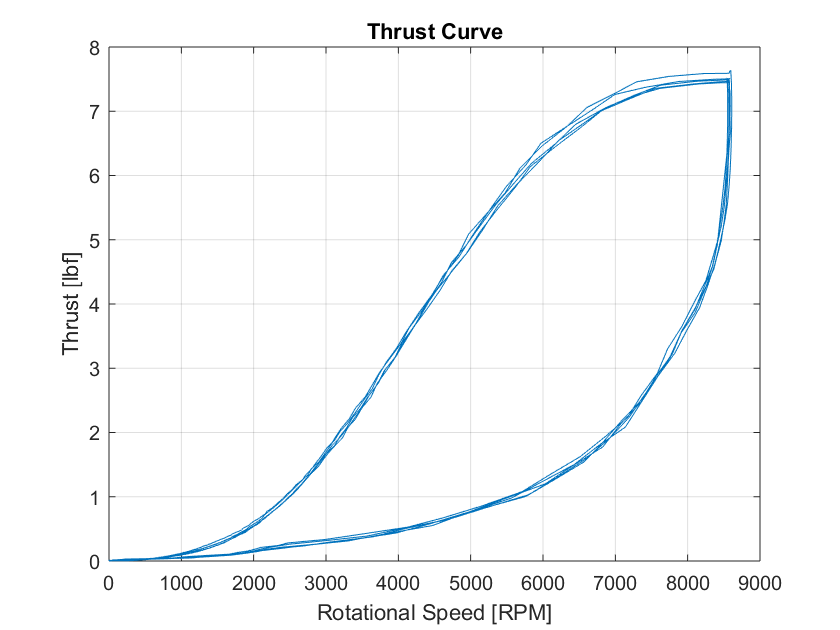

figure(1)
plot(rot_speed_rpm, T); title('Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

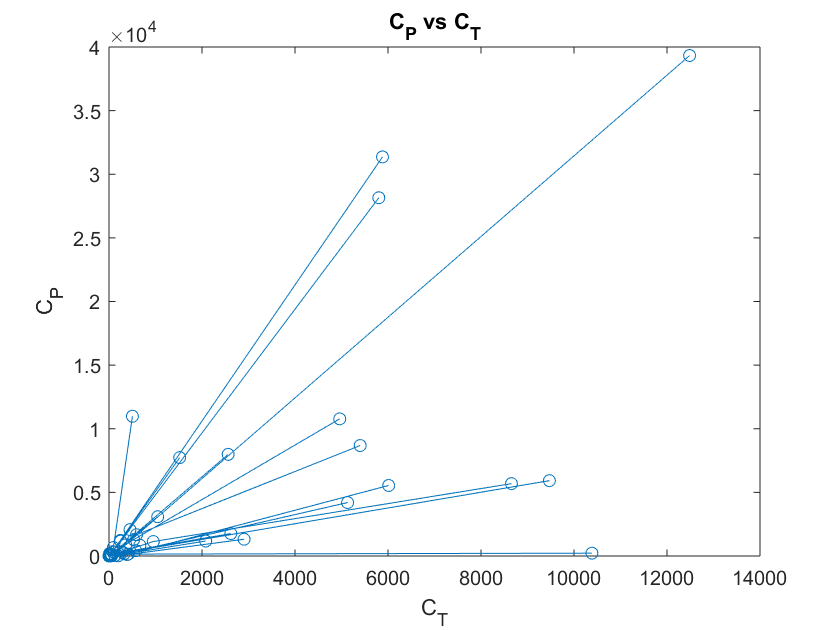


figure(2)
plot(C_T, C_P,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

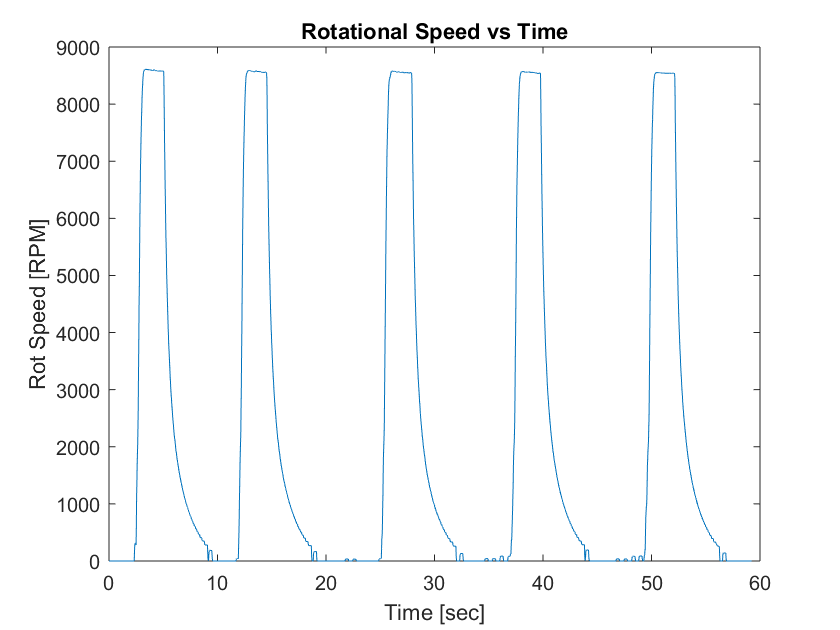


figure(3)
plot(time, rot_speed_rpm); title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

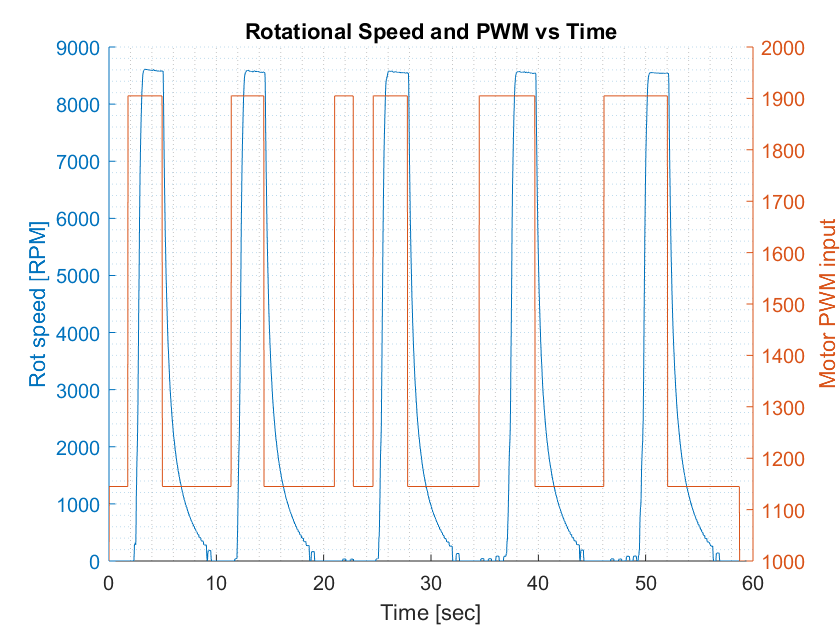


figure(4)
hold on
yyaxis left
plot(time, rot_speed_rpm);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

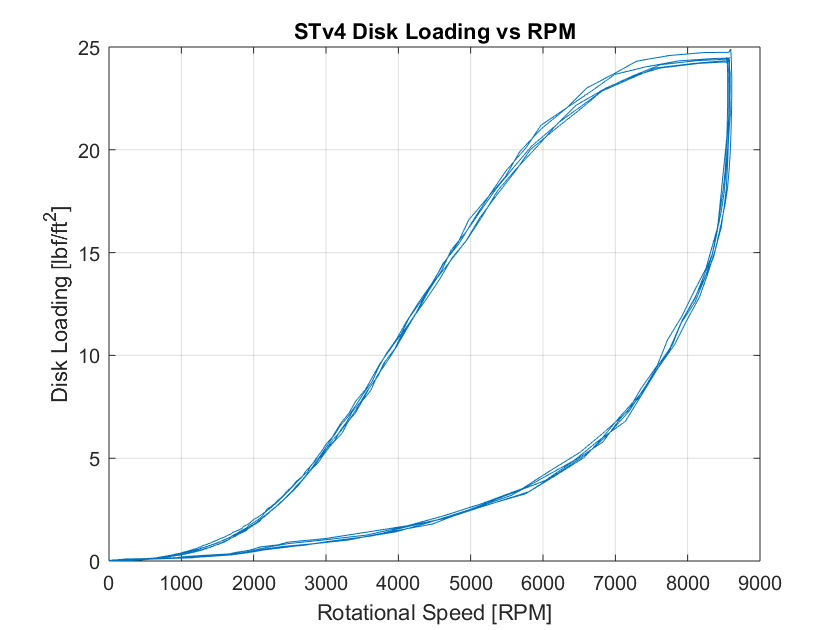


figure(5)
plot(rot_speed_rpm, disk_loading); title('STv4 Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on');

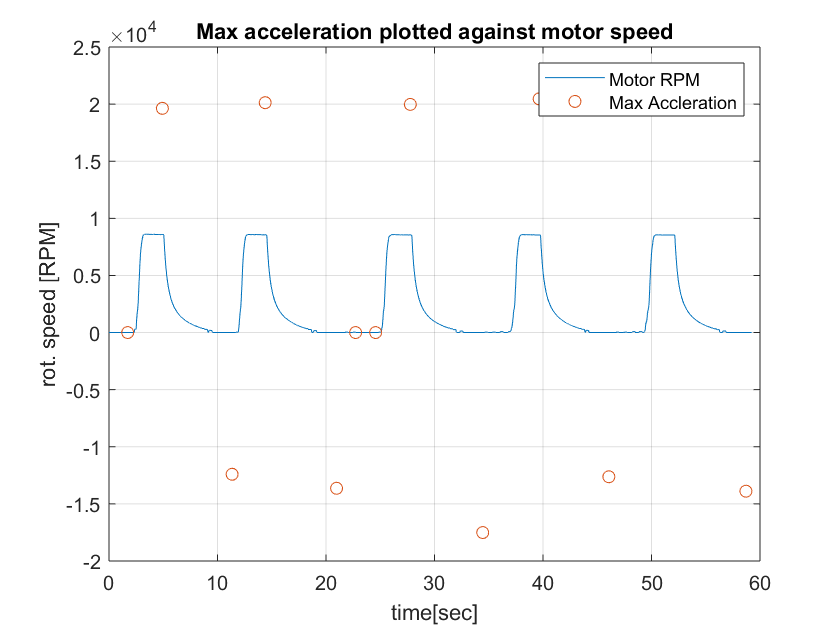


figure(6)
plot(time, rot_speed_rpm, time, Max_Acc, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');

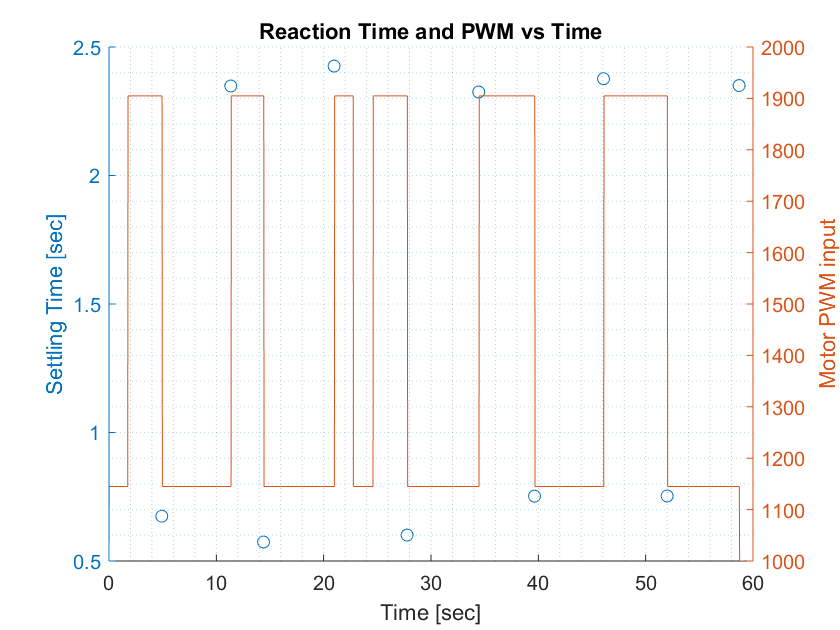


figure(7)
hold on
yyaxis left
plot(time,Settling_time, 'o-');
ylabel('Settling Time [sec]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

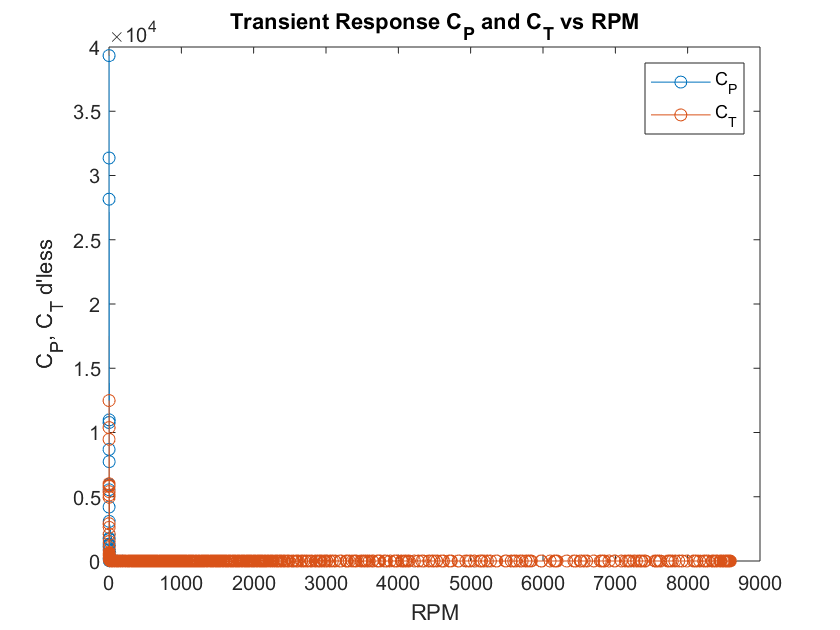


figure(9)
plot(rot_speed_rpm(188:1986), C_P(188:1986), 'o-', rot_speed_rpm(188:1986), C_T(188:1986), 'o-');
title('Transient Response C_P and C_T vs RPM'); legend('C_P', 'C_T');
xlabel('RPM'); ylabel("C_P, C_T d'less")

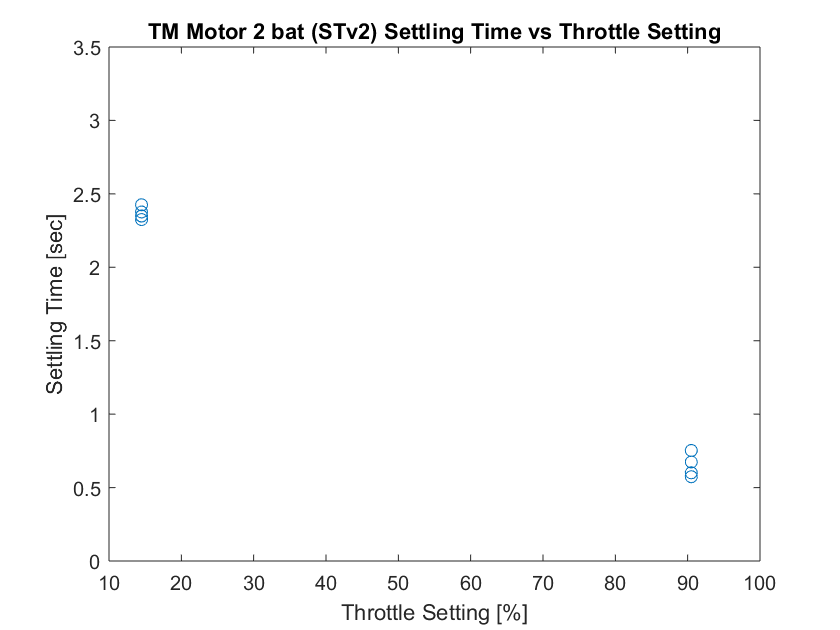


%{
figure(10)
hold on
yyaxis left
% ramp 1
plot(rot_speed_rpm(96:199), C_P(96:199));
% set
plot(rot_speed_rpm(200:365), C_P(200:365));
plot(rot_speed_rpm(370:381), C_P(370:381));
% ramp 2
plot(rot_speed_rpm(480:578), C_P(480:578));
% set
plot(rot_speed_rpm(579:748), C_P(579:748));
plot(rot_speed_rpm(755:766), C_P(755:766));
% ramp 3
plot(rot_speed_rpm(881:883), C_P(881:883));
plot(rot_speed_rpm(901:911), C_P(901:911));
% set
plot(rot_speed_rpm(912:913), C_P(912:913));
% ramp 4
plot(rot_speed_rpm(994:1104), C_P(994:1104));
% set
plot(rot_speed_rpm(1105:1264), C_P(1105:1264));
plot(rot_speed_rpm(1280:1290), C_P(1280:1290));
% ramp 5
plot(rot_speed_rpm(1371:1381), C_P(1371:1381));
plot(rot_speed_rpm(1399:1409), C_P(1399:1409));
plot(rot_speed_rpm(1426:1436), C_P(1426:1436));
plot(rot_speed_rpm(1455:1569), C_P(1455:1569));
% set
plot(rot_speed_rpm(1570:1742), C_P(1570:1742));
% ramp 6
plot(rot_speed_rpm(1838:1849), C_P(1838:1849));
plot(rot_speed_rpm(1866:1875), C_P(1866:1875));
plot(rot_speed_rpm(1892:1903), C_P(1892:1903));
plot(rot_speed_rpm(1918:1928), C_P(1918:1928));
plot(rot_speed_rpm(1935:2037), C_P(1935:2037));
% set
plot(rot_speed_rpm(2038:2186), C_P(2038:2186));
plot(rot_speed_rpm(2197:2206), C_P(2197:2206));

%legend('RU 1', 'RU 2', 'RU 3', 'RU 4', 'RU 5', 'RU6'); 
ylim([0 0.1]);
ylabel('C_P');

yyaxis right
% ramp 1
plot(rot_speed_rpm(96:199), C_T(96:199));
% set
plot(rot_speed_rpm(200:365), C_T(200:365));
plot(rot_speed_rpm(370:381), C_T(370:381));
% ramp 2
plot(rot_speed_rpm(480:578), C_T(480:578));
% set
plot(rot_speed_rpm(579:748), C_T(579:748));
plot(rot_speed_rpm(755:766), C_T(755:766));
% ramp 3
plot(rot_speed_rpm(881:883), C_T(881:883));
plot(rot_speed_rpm(901:911), C_T(901:911));
% set
plot(rot_speed_rpm(912:913), C_T(912:913));
% ramp 4
plot(rot_speed_rpm(994:1104), C_T(994:1104));
% set
plot(rot_speed_rpm(1105:1264), C_T(1105:1264));
plot(rot_speed_rpm(1280:1290), C_T(1280:1290));
% ramp 5
plot(rot_speed_rpm(1371:1381), C_T(1371:1381));
plot(rot_speed_rpm(1399:1409), C_T(1399:1409));
plot(rot_speed_rpm(1426:1436), C_T(1426:1436));
plot(rot_speed_rpm(1455:1569), C_T(1455:1569));
% set
plot(rot_speed_rpm(1570:1742), C_T(1570:1742));
% ramp 6
plot(rot_speed_rpm(1838:1849), C_T(1838:1849));
plot(rot_speed_rpm(1866:1875), C_T(1866:1875));
plot(rot_speed_rpm(1892:1903), C_T(1892:1903));
plot(rot_speed_rpm(1918:1928), C_T(1918:1928));
plot(rot_speed_rpm(1935:2037), C_T(1935:2037));
% set
plot(rot_speed_rpm(2038:2186), C_T(2038:2186));
plot(rot_speed_rpm(2197:2206), C_T(2197:2206));

ylim([0 0.1]);
ylabel('C_T');
title('C_P and C_T vs RPM');
xlabel('RPM');
grid('minor');
hold off
%}

figure(11)
plot(throttle, Settling_time, 'o');
title('TM Motor 2 bat (STv2) Settling Time vs Throttle Setting');
ylabel('Settling Time [sec]'); xlabel('Throttle Setting [%]');
ylim([0 3.5]);

## Comparing Data to Momentum Theory

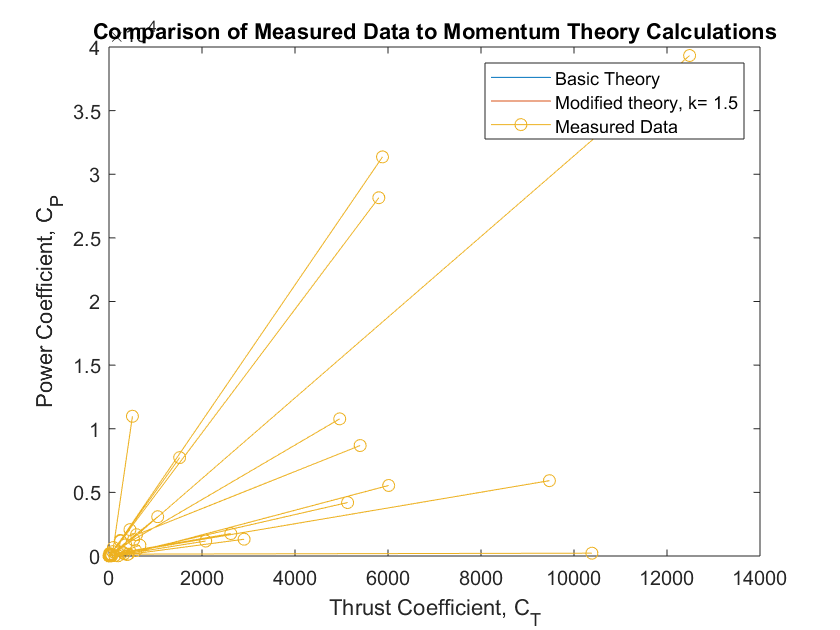

k = 1.5;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T(188:1986), C_P(188:1986), 'o-');
title('Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.5', 'Measured Data')